# **Siganals and Systems - Dr. Akhavan**

## CA1** - Matin Bazrafshan**

# **Part 1:**

**Q1.1: **the `hold on` command is used to retain existing plots on a figure when adding new plots. If we don't use `hold on`, MATLAB clear the current figure and display only the last created plot, so it is same to use `clf` before each new plot.

**Q1.2: **The `subplot` function in MATLAB is used to create a grid of smaller subplots within a single figure, so it will be easy to read and compare.

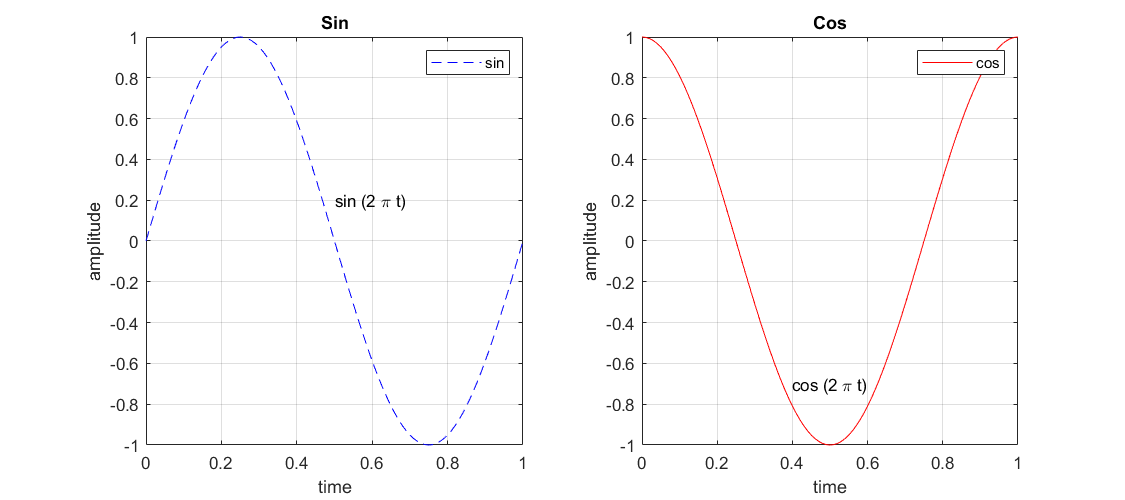

clearvars;
t = 0:0.01:1;
zl = sin(2*pi*t);
z2 = cos(2*pi*t);

figure('Position', [0 0 900 400]);

subplot(1, 2, 1);
plot(t, zl, '--b')
title('Sin');
legend('sin');
s = 'sin (2 \pi t)';
text(0.5, 0.2, s);
xlabel('time');
ylabel('amplitude');
grid on;

subplot(1, 2, 2);
plot(t, z2, 'r')
title('Cos');
legend('cos');
s = 'cos (2 \pi t)';
text(0.4, -0.7, s);
xlabel('time');
ylabel('amplitude');
grid on;

# Part 2:

clearvars;
load('files/p2.mat');

**Q2.1:**

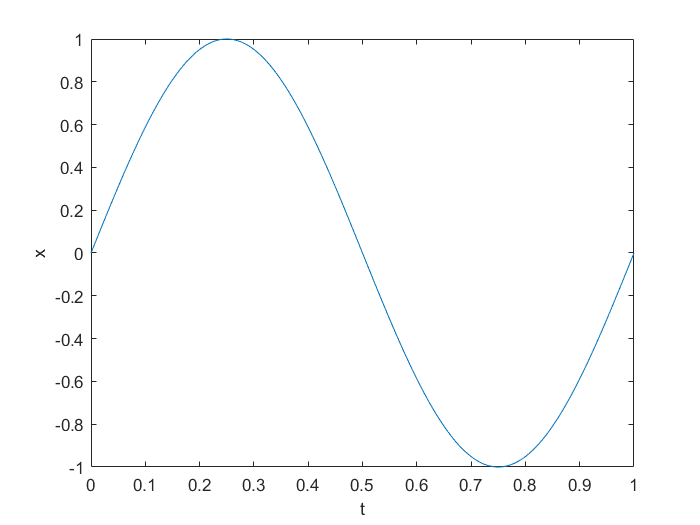

figure;
plot(t,x);
xlabel('t');
ylabel('x');

**Q2.2:**

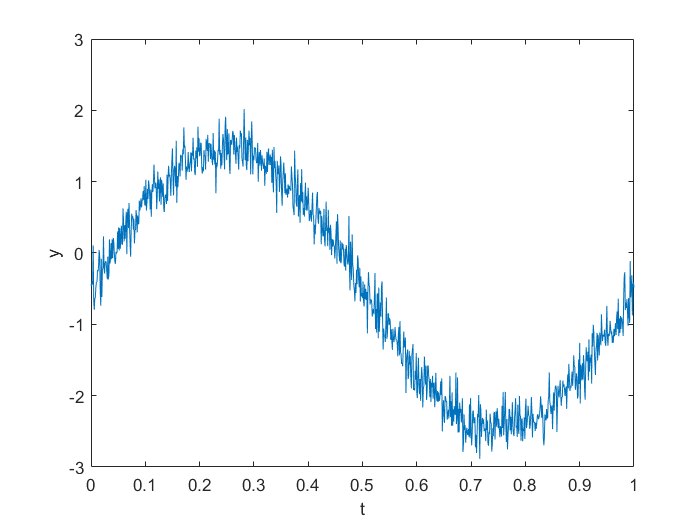

plot(t,y);
xlabel('t');
ylabel('y');

**Q2.3:** If we conside y = a × x + b so, a is slope of noise and b is intercept of it.

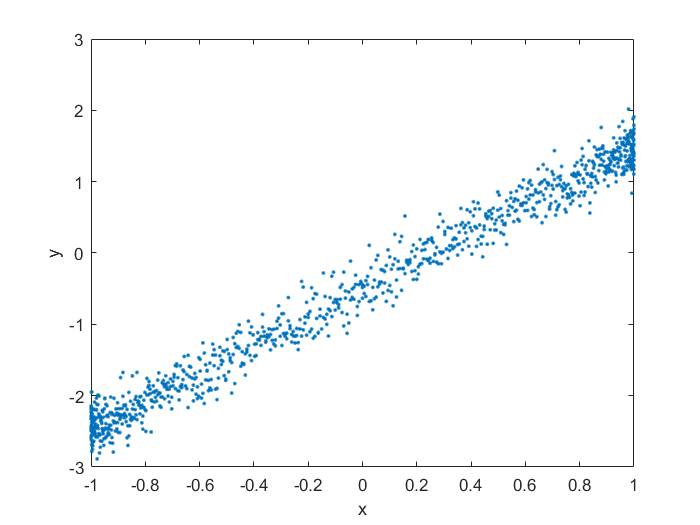

plot(x,y,'.')
xlabel('x');
ylabel('y');

**Q2.4:** To calculate alpha and beta we can define an error function $f\left(a,b\right)=\sum_t {\left(y_t -\left(\alpha x_t +\beta \right)\right)}^2 \;$ , so by minimizing this function, we can calculate alpha and beta, so:


$$\begin{array}{l}
\frac{\partial }{\partial \beta }f=0\to \sum_t y_t -\left(\alpha \ldotp x_t +\beta \right)=0\to y_{\mathrm{sum}} -\alpha \ldotp x_{\mathrm{sum}} -t\ldotp \beta =0\to \beta =y_{\mathrm{avg}} -\alpha \ldotp x_{\mathrm{avg}} \\
\frac{\partial }{\partial \alpha }f=0\to \sum_t x_t \left(y_t -\left(\alpha \ldotp x_t +\beta \right)\right)=0\to \sum_t x_t \;y_t -a\ldotp x_t^2 -x_t \beta =0\to \;\beta =y_{\mathrm{avg}} -\alpha \ldotp x_{\mathrm{avg}} \to \alpha =\frac{\sum_t \left(x_t -x_{\mathrm{avg}} \right)\left(y_t -y_{\mathrm{avg}} \right)}{\sum_t {\left(x_t -x_{\mathrm{avg}} \right)}^2 }
\end{array}$$


[a, b] = regressioner(x,y)

a = 1.9736

b = -0.4983

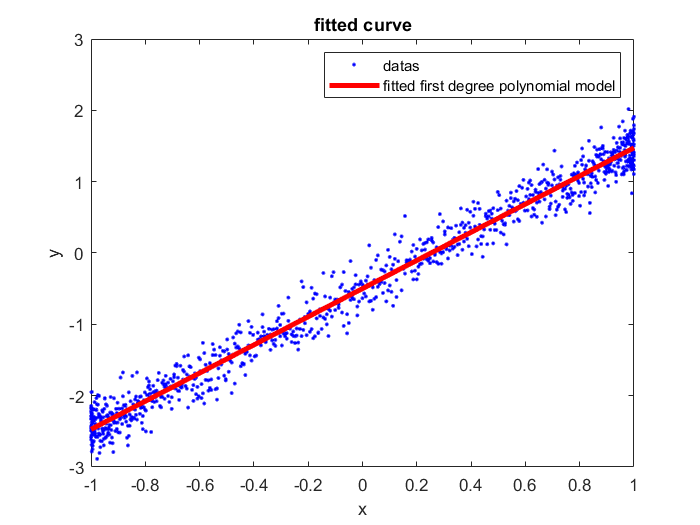

figure;
plot(x,y,'b.');
hold on;
u = -1:0.01:1;
plot(u, a .* u + b, 'r', 'LineWidth', 3);
legend('datas', 'fitted first degree polynomial model')
xlabel('x');
ylabel('y');
title('fitted curve')

**Additional: Gradient-Descent**

To double-check the answer, gradient descent algorithm can be used too, it is an algorithm which update the parameters of a function iteratively by taking steps proportional to the negative gradient of the error function at each step and optimize the variables.

$\hat{y} = w \times x + b$ , $J = \frac{\sum_{i=1}^{n} (y^{(i)} - \hat{y}^{(i)})^2}{n}$

$w \to w - \alpha \times \frac{\partial J}{\partial w}$ , $b \to b - \alpha \times \frac{\partial J}{\partial b}$

- $\alpha \;$is learning rate

- w is slope

- b is intercept

- J is loss function(same as error). We used RMSE as loss function.

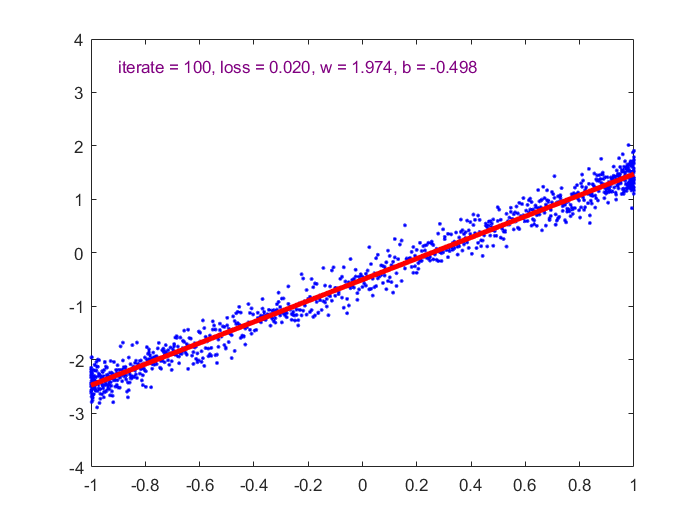

learning_rate = 0.3;
w = 10;
b = 10;
figure;
for i=1:100
    dw = 1/length(x) * sum((x .* (w .* x + b - y)));
    db = 1/length(x) * sum(w .* x + b - y);
    w = w - dw * learning_rate;
    b = b - db * learning_rate;
    cla;
    plot(x,y,'b.');
    hold on;
    u = -1:0.01:1;
    plot(u,w.*u+b,'r','LineWidth', 3);
    axis([-1, 1, -4, 4]);
    text(-0.9,3.5,sprintf('iterate = %d, loss = %.3f, w = %.3f, b = %.3f', i, loss(y,x,w,b), w, b),'Color','#800080');
    drawnow;
    pause(0.1)
end

It can be seen that the same results are achived:

w, b

w = 1.9736

b = -0.4983

**Q2.5:** Now we can use built-in app for curve fitiing in MATLAB:

- We can see, estimated slope is 1.974 and intercept is -0.4983 with sum square error of 39.86 and R-squared of 0.9799, which means we found a good fit. 

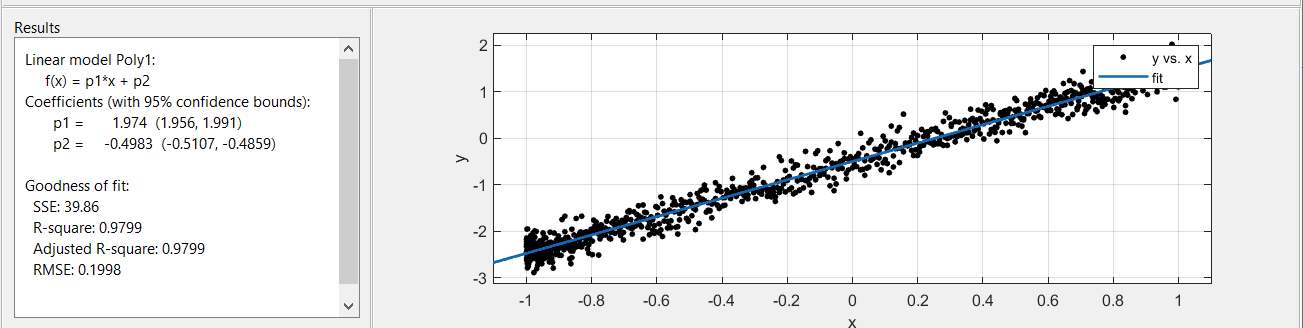

# Part 3:

In this section we want to calculate distance of a car by send and receive a signal and then proccess it.

                                    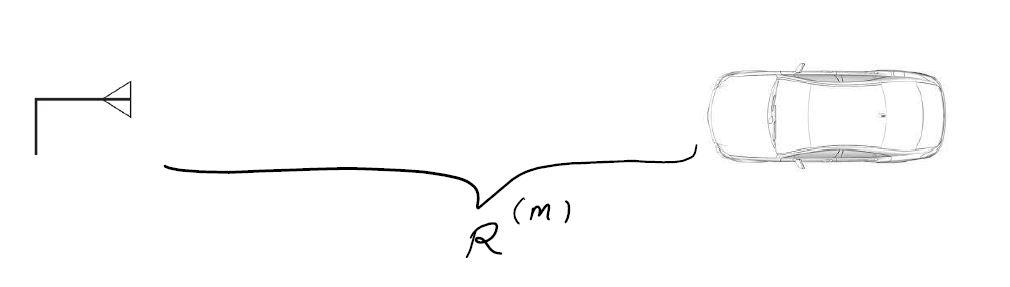

**Q3.1:** First we send a signal:

                                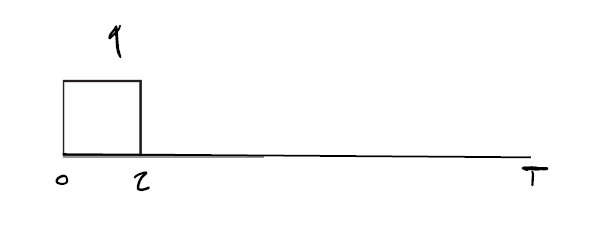

which is

- T = ${10}^{-5}$

- $f_s$ (sampling rate) = ${10}^{-9}$

- 
$$\tau ={10}^{-6}$$


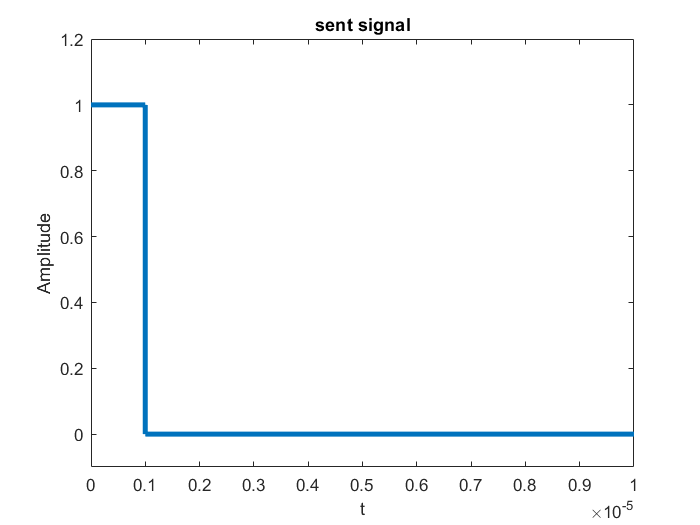

clearvars;
ts = 1e-9;
T = 1e-5;
tau = 1e-6;

t = 0:ts:T;
x = zeros(size(t));
x(1:int64(tau/ts)) = 1;
figure;
plot(t,x,'LineWidth',3);
axis([0 1e-5 -0.1 1.2]);
xlabel('t');
ylabel('Amplitude');
title('sent signal');

**Q3.2:** Then we recieve a signal which is:

                            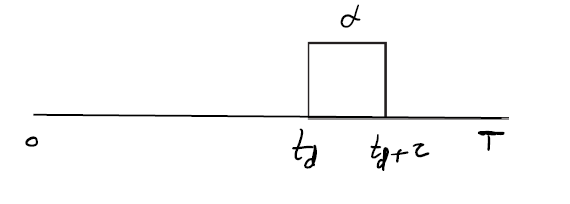

- 
$$\alpha =0\ldotp 5$$


- $t_d \;$will be calculated 

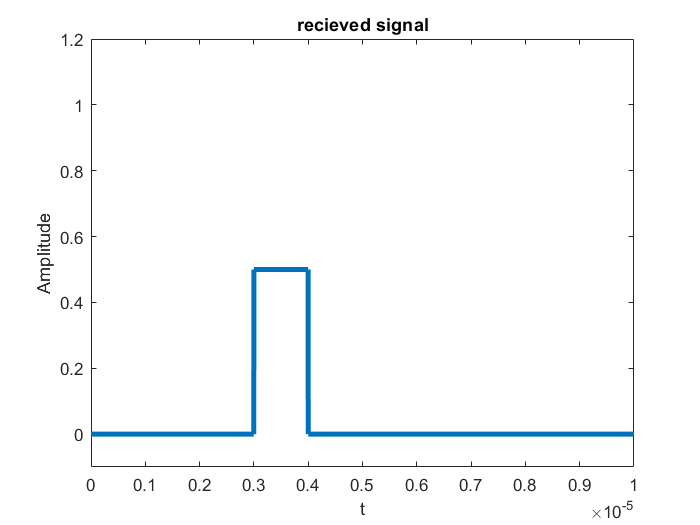

R = 450;
c = 3e8;
td = 2 * R / c;

input_signal = zeros(size(t));
alpha = 0.5;
input_signal(int64(td/ts):int64((td+tau)/ts)) = 0.5;
figure;
plot(t,input_signal,'LineWidth',3);
axis([0 1e-5 -0.1 1.2]);
xlabel('t');
ylabel('Amplitude');
title('recieved signal');

**Q3.3:** R is unknown and is meant to be calcuated. if we consider signals has speed of light $c\;=\;3\times {10}^8 \;\frac{m}{s}$ so we can estimate $R=\frac{t_d \times c}{2}$. 

$t_d$ can be obtained by shifting sent signal and computing its correlation with input signal.

Template matching is a technique that uses correlation to compare a reference signal (template) with a larger signal to determine the presence and location of the template. It is often used in image processing and pattern recognition applications.

                        
$$corr(x,y) = \frac{n\sum\limits_{i=1}^n x_i y_i - \sum\limits_{i=1}^n x_i \sum\limits_{i=1}^n y_i}{\sqrt{(n\sum\limits_{i=1}^n x_i^2 - (\sum\limits_{i=1}^n x_i)^2)(n\sum\limits_{i=1}^n y_i^2 - (\sum\limits_{i=1}^n y_i)^2)}}$$


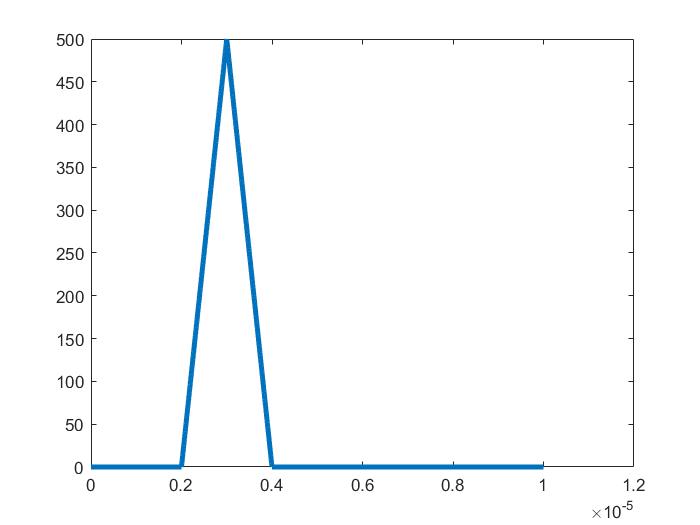

ro = calc_corr(t, tau, ts, input_signal);
plot(t,ro,'LineWidth',3);

[a, max_corr] = max(ro);
td = t(max_corr);
estimated_R = td * c / 2

estimated_R = 449.8500

**Q3.4:** But unfortunately input signals are mostly noisy, we simulate noise by adding some random numbers based on normal distribution, then we increse noise as estimated distance get far from its real value.(real distance is 450m.)

To reduce randomness, we repeat every noise 100 times, and average the errors. We continue raising noise until the error reaches 15 meters.

noise = 0;
k = 100;
R = 450;
noise_raise = 0.1;
errors = zeros(1,k);
Rs = zeros(1,k);
last_err = 0;
i = 1;
while(last_err < 15)
    sum_err = 0;
    sum_R = 0;
    for j=1:100
       ro = calc_corr(t, tau, ts, input_signal + noise * randn(size(input_signal)));
       [a, max_corr] = max(ro);
       estimated_R = t(max_corr) * c / 2;
       sum_err = sum_err + abs(R - estimated_R);
       sum_R = sum_R + estimated_R;
    end
    errors(i) = sum_err / 100;
    Rs(i) = sum_R / 100;
    last_err = errors(i);
    i = i + 1;
    noise = noise + noise_raise;
end

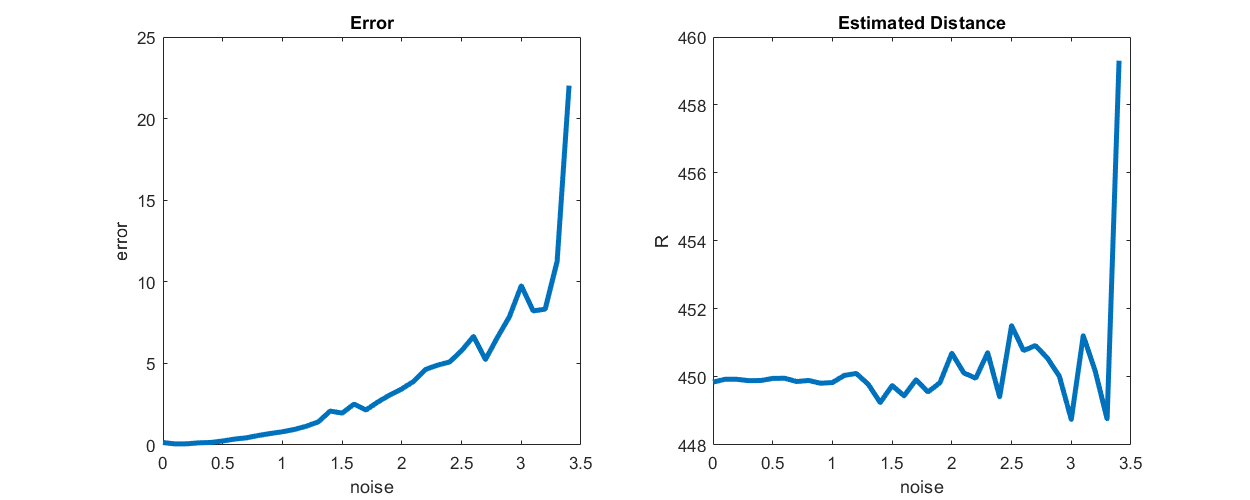

last = i - 1;
u = (0 : noise_raise : noise_raise * (last - 1));
figure('Position', [0 0 1000 400]);

subplot(1, 2, 1);
plot(u, errors(1:last), 'LineWidth', 3);
title('Error');
xlabel('noise');
ylabel('error');

subplot(1, 2, 2);
plot(u, Rs(1:last), 'LineWidth', 3);
title('Estimated Distance');
xlabel('noise');
ylabel('R');

# Part 4:

**Q4.1: **sample rate is number of samples(from voice array) which be played at a second.

clearvars;
[soundData, sampleRate] = audioread('.\Beit.ogg');
sampleRate

sampleRate = 48000

**Q4.2: **We have an arrays of sample, by dividing this size to sample rate we will got time of voice.

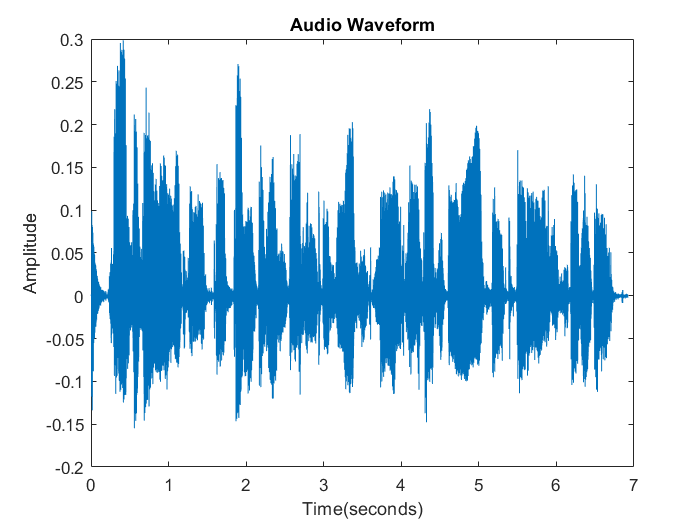

t = (0:length(soundData)-1) / sampleRate;

figure;
plot(t, soundData);
xlabel('Time(seconds)');
ylabel('Amplitude');
title('Audio Waveform');

Note: You can uncomment the sound to hear the voice:

%sound(soundData, sampleRate);
audiowrite('x.wav', soundData, sampleRate);

**Q4.3:**

As we can see we have almost similar sound wave but with different scales at x-axix which is time, so we got almost same audio in speed = 2 at half of normal time and almost same one at double of normal time when speed = 0.5.

To have a sound twice as fast we need to take half of samples, so we take one sample out of two every two samples.

To have a sound with half speed, we need to double the size of samples, so we add another sample between every two sample, which its value is average of those two samples. 

Note: you can set last argument of function to `true/false `to hear the voice if you want.


$$\begin{array}{l}
f_{2s} \left(x\right)=f\left(2x\right)\\
f_{\frac{s}{2}} \left(x\right)=\frac{f\left(\left\lfloor \frac{x}{2}\right\rfloor \right)+f\left(\left\lceil \frac{x}{2}\right\rceil \right)}{2}
\end{array}$$


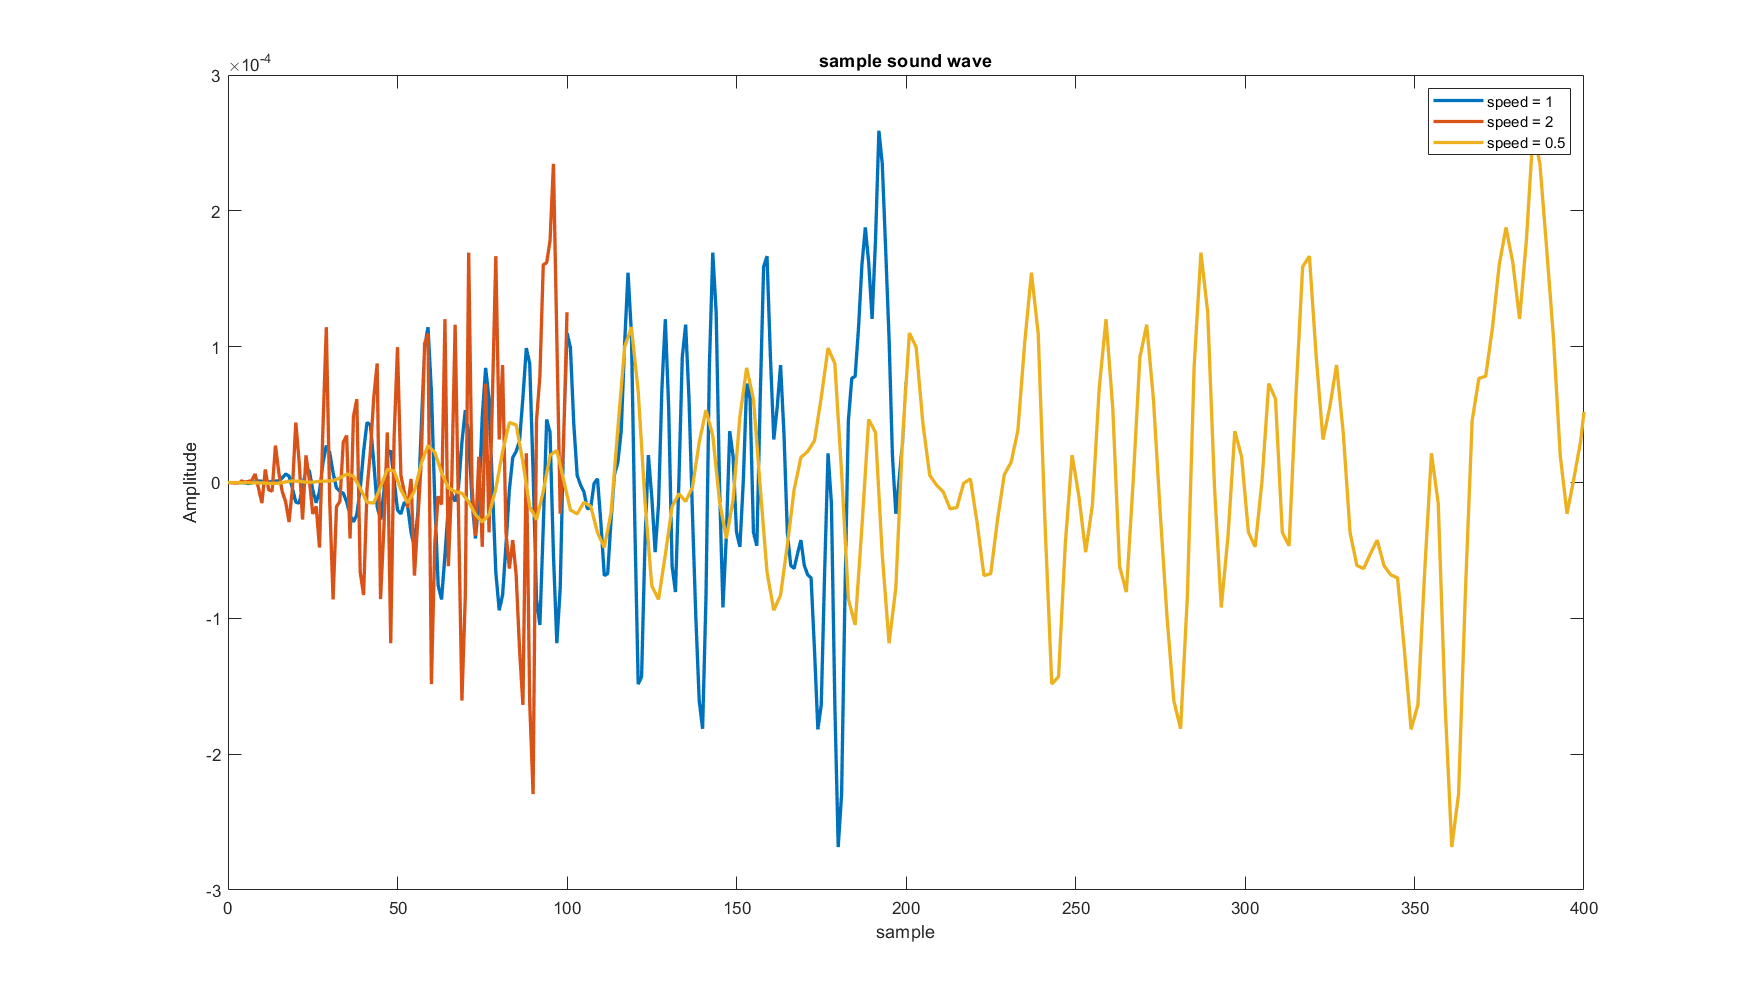

figure('Position', [0 0 1400 800]);

k = 200;

u = 0:k;  
plot(u,soundData(1:length(u)),'LineWidth',2);
xlabel('sample');
ylabel('Amplitude');
hold on;

u = 0:k/2;
speed2 = playback_speed_half_twice(soundData, 2, sampleRate, false);
plot(u,speed2(1:length(u)),'LineWidth',2);
xlabel('sample');
ylabel('Amplitude');

hold on;
u = 0:2*k;
speed_5 = playback_speed_half_twice(soundData, 0.5, sampleRate, false);
plot(u,speed_5(1:length(u)),'LineWidth',2);
xlabel('sample');
ylabel('Amplitude');

title('sample sound wave');
legend('speed = 1','speed = 2','speed = 0.5');

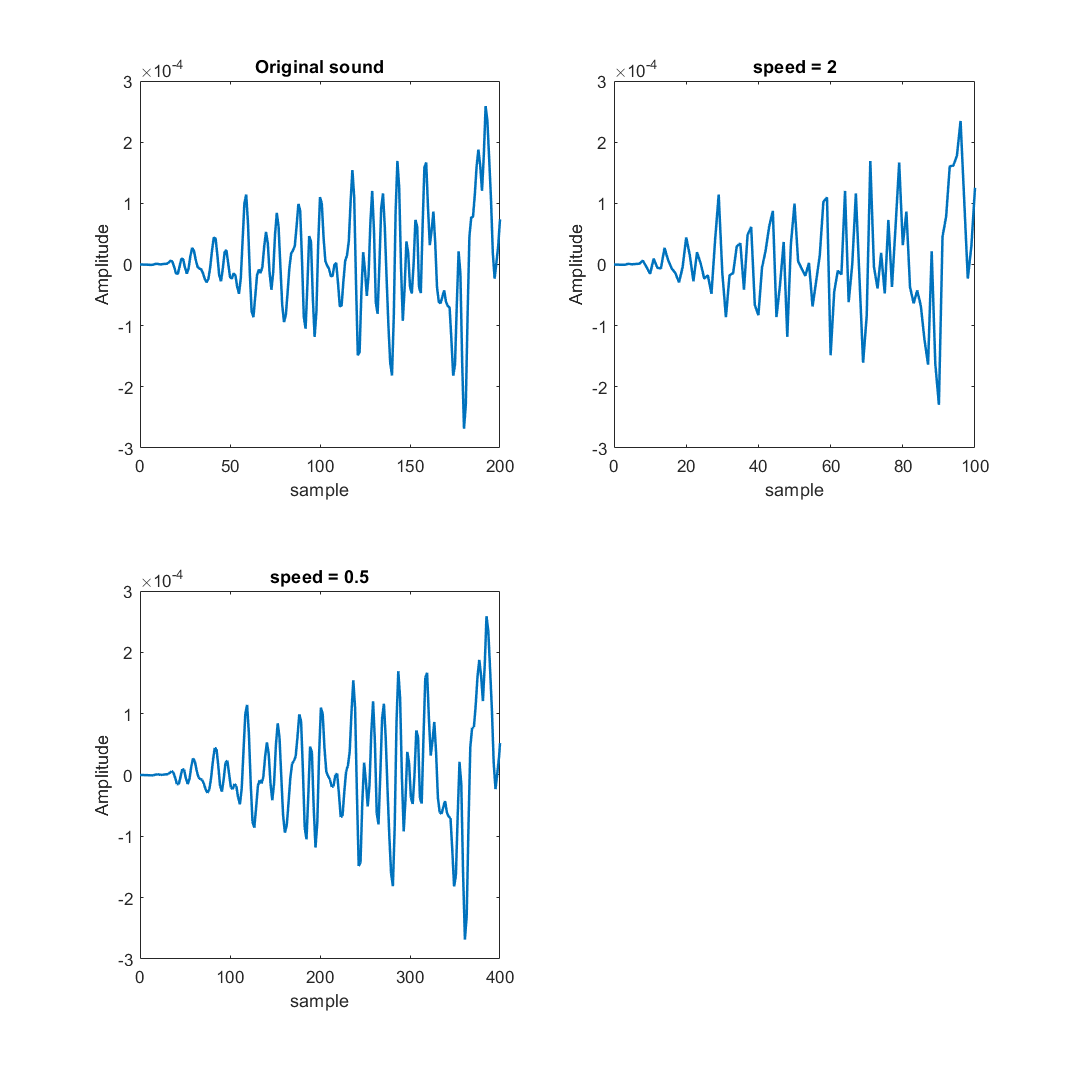

figure('Position', [0 0 2000 2000]);

k = 200;

subplot(2, 2, 1);
u = 0:k;  
plot(u,soundData(1:length(u)),'LineWidth',1.5);
xlabel('sample');
ylabel('Amplitude');
title('Original sound');

subplot(2, 2, 2);
u = 0:k/2;
speed2 = playback_speed_half_twice(soundData, 2, sampleRate, false);
plot(u,speed2(1:length(u)),'LineWidth',1.5);
xlabel('sample');
ylabel('Amplitude');
title('speed = 2');

subplot(2, 2, 3);
u = 0:2*k;
speed_5 = playback_speed_half_twice(soundData, 0.5, sampleRate, false);
plot(u,speed_5(1:length(u)),'LineWidth',1.5);
xlabel('sample');
ylabel('Amplitude');
title('speed = 0.5');

As you can see, when we seperate them, they are also same but pay attention to x-axis.

**Q4.4:**

To have a sound with desired speed, we need to reduce/increase sample by 1/s, which s is new size, so we take every 1/s sample, according to the fact that x/s could be a non-integer number, we choose two nearest sample by choosing floor and ceil of x/s.


$$f_s \left(x\right)=\frac{f\left(\left\lfloor \frac{x}{s}\right\rfloor \right)+f\left(\left\lceil \frac{x}{s}\right\rceil \right)}{2},s=\textrm{new}\;\textrm{rate}$$


Note: you can set last argument of function to `true/false `to hear the voice if you want.

As you will see when we increase speed ratio we lose some part of voice and when we decrease it we add some more samples in our voice array by averaging samples(some kind of interpolation), consider that, sample rate will not be changed instead array length changes.


$$\textrm{length}\left(f_s \right)=\frac{\textrm{length}\left(f\right)}{s}$$


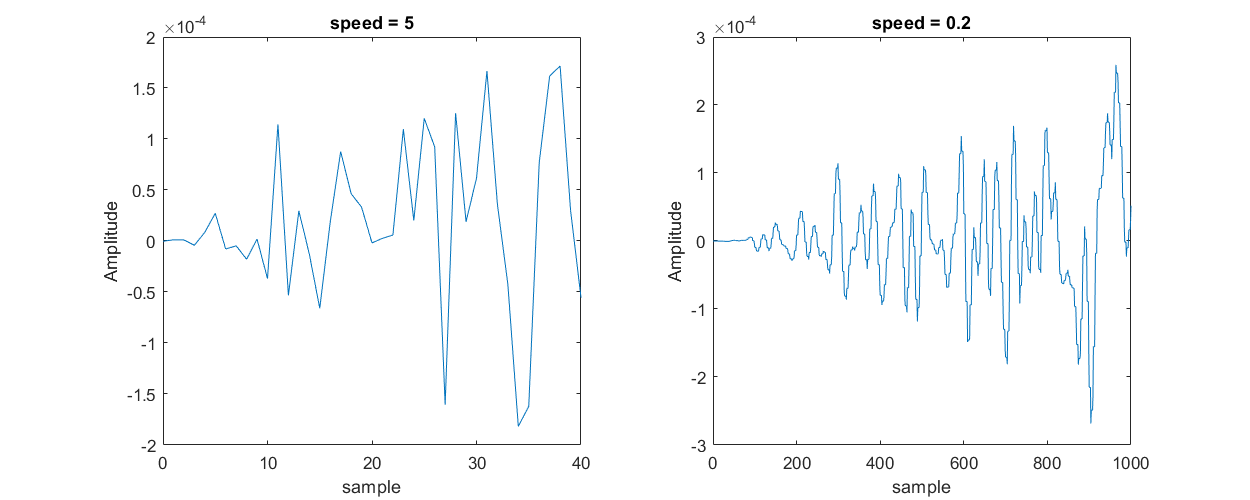

figure('Position', [0 0 1000 400]);

k = 200;

subplot(1, 2, 1);
u = 0:k/5;  
speed5 = playback_speed(soundData, 5, sampleRate, false);
plot(u,speed5(1:length(u)));
xlabel('sample');
ylabel('Amplitude');
title('speed = 5');

subplot(1, 2, 2);
u = 0:k*5;
speed_2 = playback_speed(soundData, 0.2, sampleRate, false);
plot(u,speed_2(1:length(u)));
xlabel('sample');
ylabel('Amplitude');
title('speed = 0.2');

You can hear the voice with chosen speed:

speed = 0.9 % randi([1,50]) / 10

speed = 0.9000

playback_speed(soundData, speed, sampleRate, true);
%clear sound

All Functions:

Note: naming could be different. According to project, standart format is followed.

function [a,b] = regressioner(x,y) % calculate alpha(slope) and beta(intercept)
    a = sum((x - mean(x)) .* (y - mean(y))) / sum((x - mean(x)).^2);
    b = mean(y) - a * mean(x);
end

% play sound in 0.5 or 2
function[newSound] = playback_speed_half_twice(soundData, speed, sampleRate, play)  

    if(speed == 2)
        newLength = round(length(soundData)/2);
        newSound = zeros(1,newLength);
        for i = 1:newLength
            newSound(i) = soundData(2 * i);
        end
        
    elseif(speed == 0.5)
        newLength = length(soundData) * 2;
        newSound = zeros(1,newLength);
        for i = 1+1:newLength-1
            if(mod(i,2) == 0)
                newSound(i) = soundData(i / 2);
            else
                newSound(i) = (soundData((i + 1) / 2) + soundData((i - 1) / 2)) / 2;
            end
        end
    
    elseif(speed == 1)
        newSound = soundData;
        
    else
        error('playSpeed must be 1 or 2 or 0.5!');
    end
    if(play)
        sound(soundData, sampleRate);
    end
end

% play sound in x.y which x in [1,9] and y in [0,9]
function[newSound] = playback_speed(soundData, speed, sampleRate, play)

    if((speed == 0) || (mod(10*speed,1) ~= 0))
        error('wrong speed! the format must be x.y which x in [1,9] and y in [0,9]');
    end
    
    newLength = floor(length(soundData) / speed);
    newSound = zeros(1,newLength);
    for i = ceil(1/speed):newLength
        newSound(i) = (soundData(floor(speed * i)) + soundData(ceil(speed * i))) / 2;
    end
    if(play)
        sound(newSound, sampleRate);
    end
end

% loss function for gradient descent
function loss = loss(y,x,w,b)
    loss = sum((y-(w .* x + b)).^2) / (2 * length(x));
end

% calculate correlation
function ro = calc_corr(t, tau, ts, input_signal)
    ro = zeros(size(t));
    for i=1:length(t)-int64(tau/ts)
        template_signal = zeros(size(t));
        template_signal(i:i+int64(tau/ts)-1) = 1;
        ro(i) = sum(template_signal .* input_signal);
    end
end